clc; close all; clear;

inDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ3_z3781\Vacuum FOA\UXI PHC\');


## Load

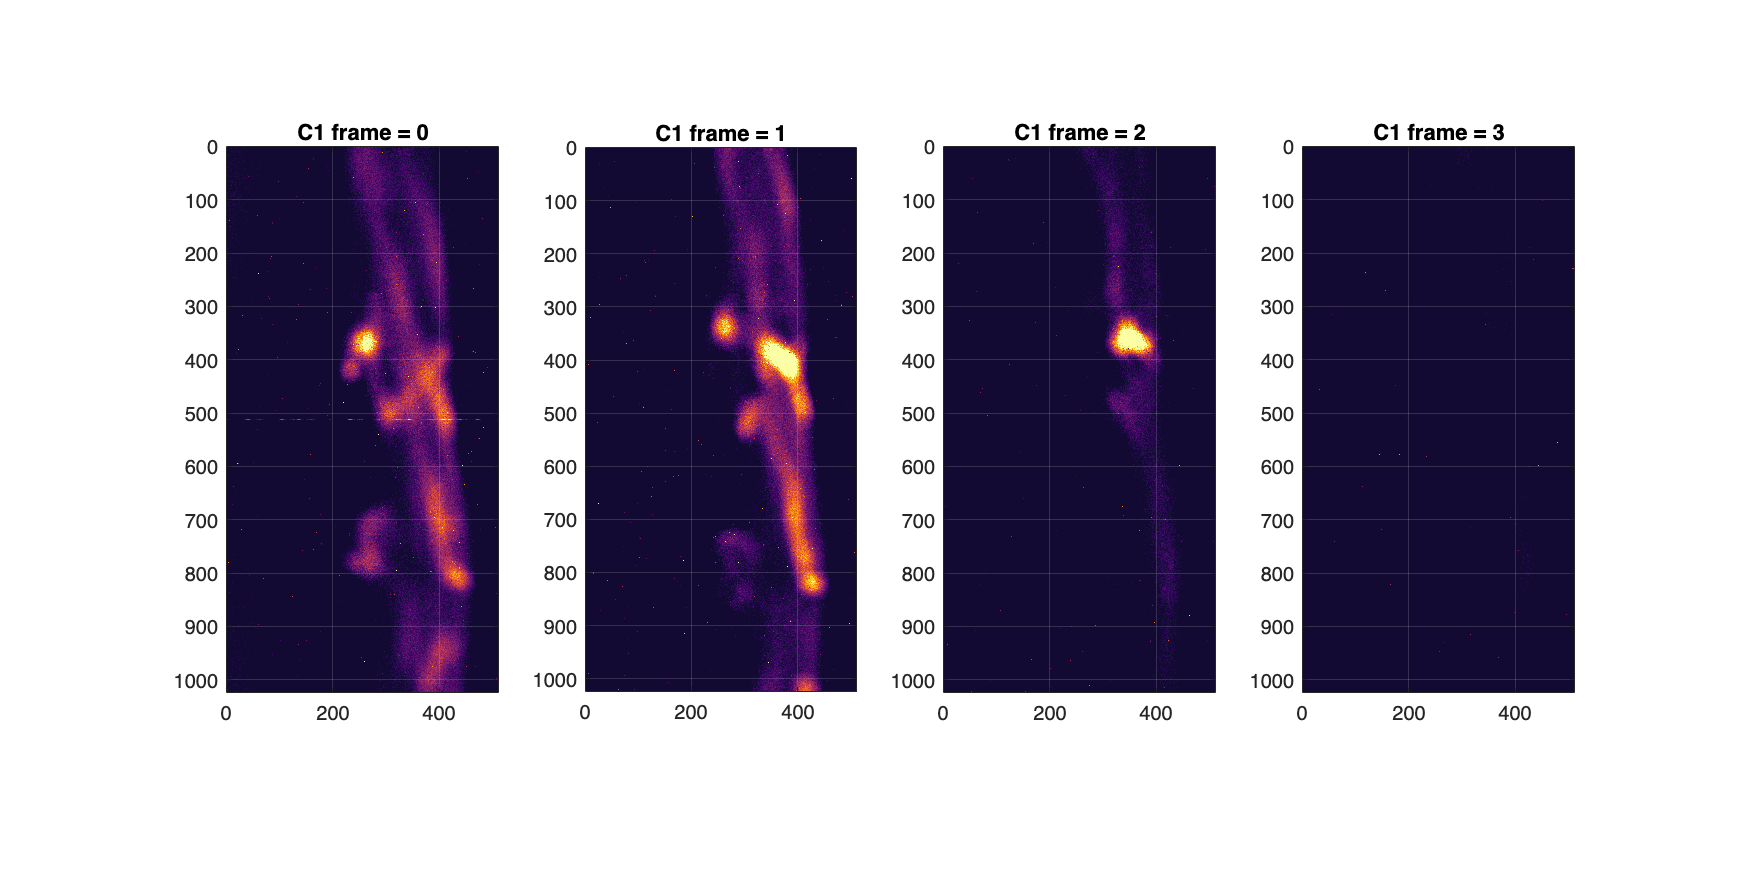


camera = 1;
figure
for ii = 0:3
subplot(1,4,ii+1)
sub_img = loadUXI(inDir,camera,ii);
imagesc(sub_img);
colormap(inferno());
grid on
ax = gca;
ax.GridColor = [1,1,1];  % [R, G, B]
axis equal
caxis([-2,20])
[m,n] = size(sub_img);
xlim([0,n]); ylim([0,m]);
title(['C' num2str(camera) ' frame = ' num2str(ii)]); 
end
set(gcf,'Position',[0 0 1800 900])

## Use frames 0 & 1

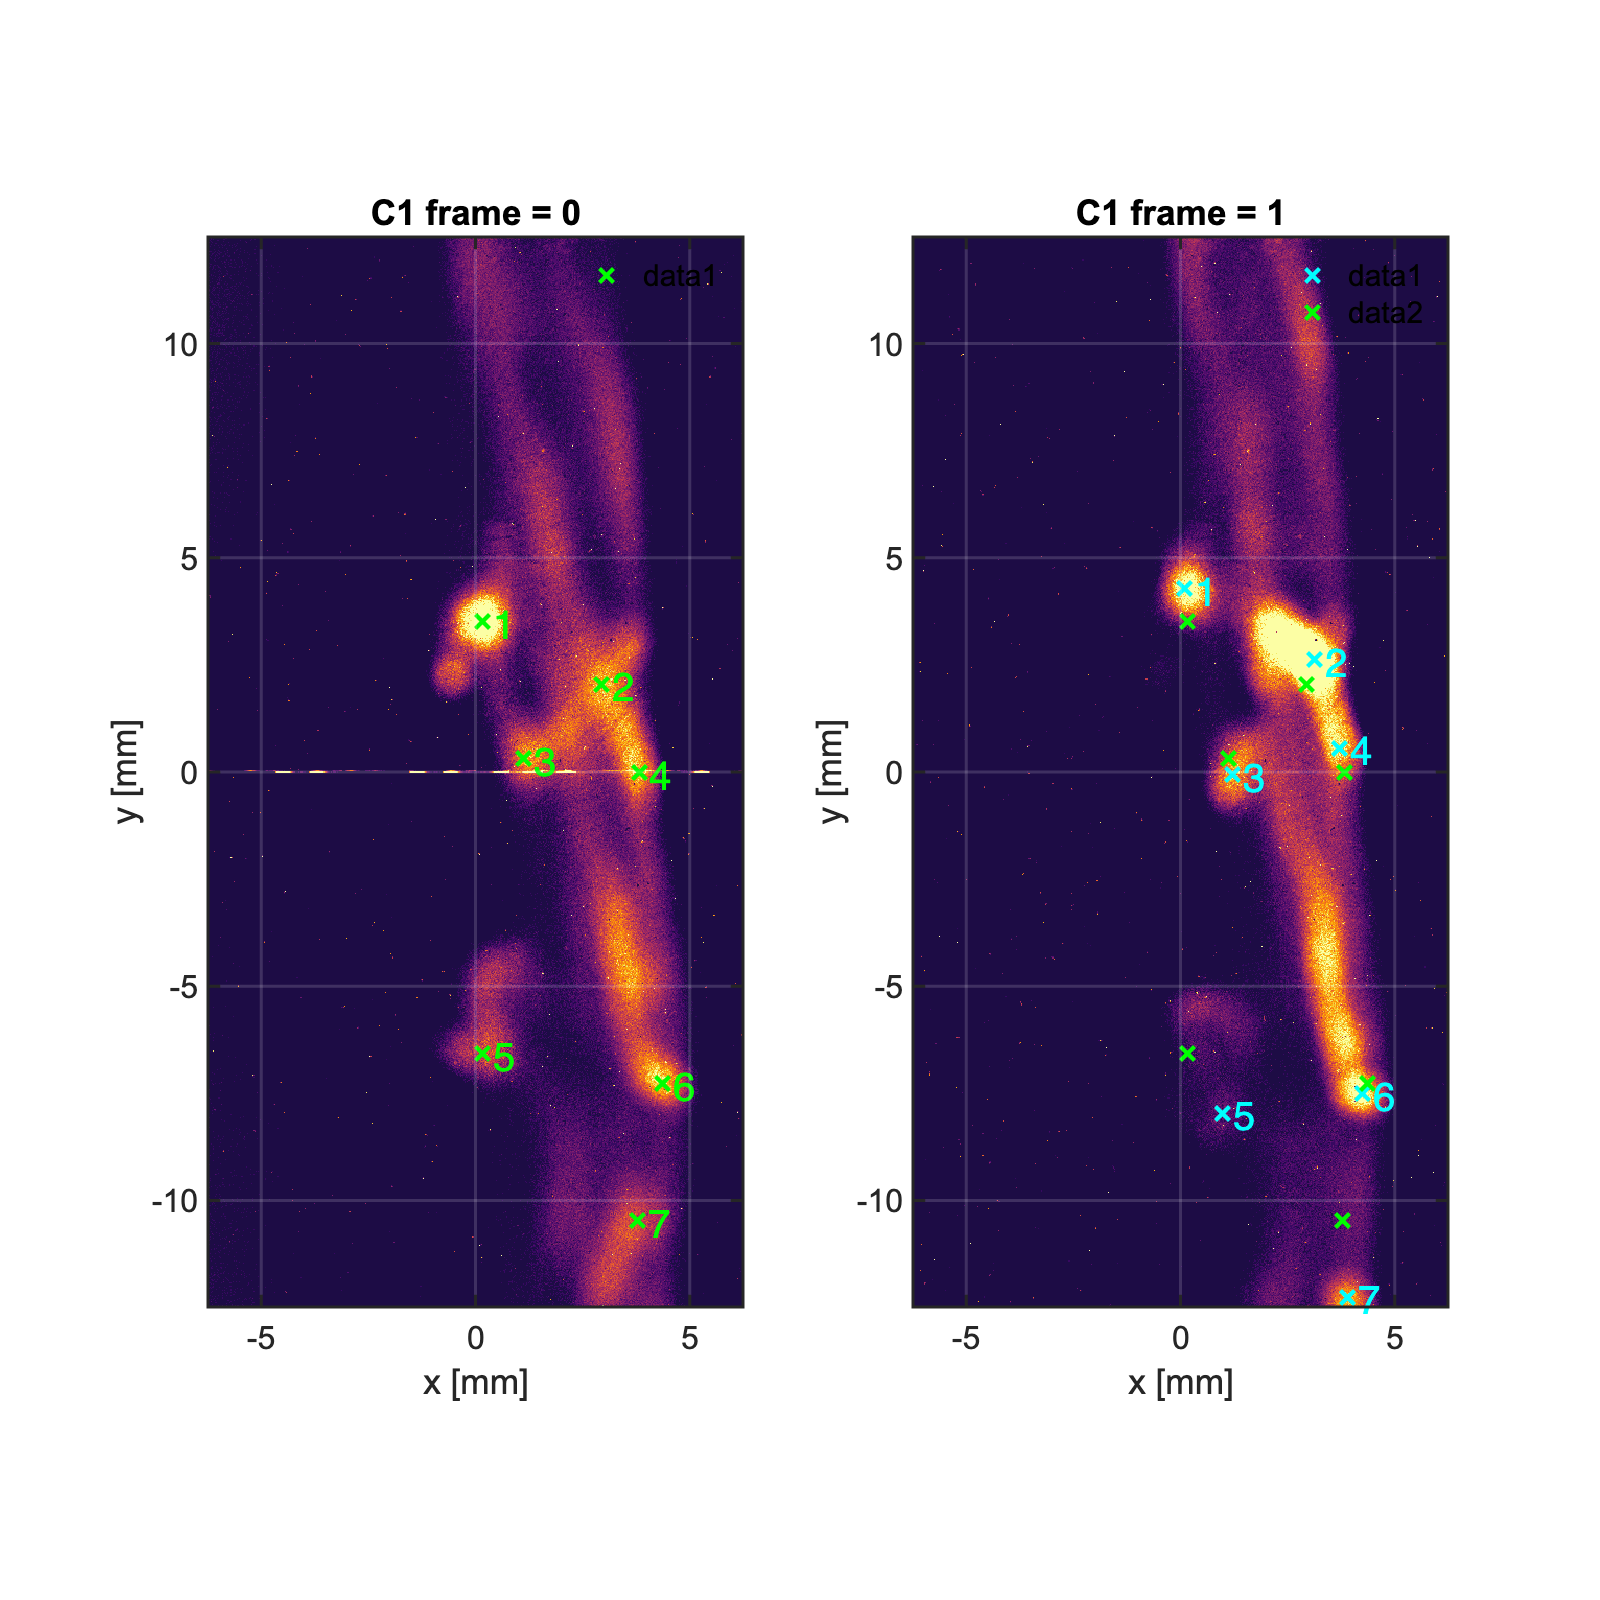

camera = 1;
frames = [0,1];
f0 = loadUXI(inDir,camera,frames(1));
f1 = loadUXI(inDir,camera,frames(2));
new = false; % set to true for new
saveDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN\Data\MARZ\UXI\processed');
L = 25;
[m,n] = size(f0);
xtickvals = [-5,0,5];
ytickvals = -10:5:10;
scale = L / m; % mm/px

f0 = flipud(f0);
f1 = flipud(f1);


figure
subplot(1,2,1)
imagesc(f0);
xlabel('x [mm]'); ylabel('y [mm]');
colormap(inferno());
grid on
ax = gca;
ax.GridColor = [1,1,1];  % [R, G, B]
axis equal
caxis([-2,15])
[m,n] = size(sub_img);
xlim([0,n]); ylim([0,m]);
formatPlots();set(gca, 'Fontsize',16);
title(['C' num2str(camera) ' frame = ' num2str(0)]); 
set(gca,'YDir','normal')
addScale(scale,f0,xtickvals,ytickvals);



subplot(1,2,2)
imagesc(f1);
xlabel('x [mm]'); ylabel('y [mm]');
colormap(inferno());
grid on
ax = gca;
ax.GridColor = [1,1,1];  % [R, G, B]
axis equal
caxis([-2,15])
[m,n] = size(sub_img);
xlim([0,n]); ylim([0,m]);
title(['C' num2str(camera) ' frame = ' num2str(1)]); 
formatPlots(); set(gca, 'Fontsize',16);
set(gcf,'Position',[0 0 900 900]);
set(gca,'YDir','normal')
addScale(scale,f1,xtickvals,ytickvals);



subplot(1,2,1);
if new
    [x0,y0] = getpts;
    x0 = x0(1:end-1); y0 = y0(1:end-1);
    save([saveDir, 'UXI' num2str(camera) num2str(frames(1)) '-' num2str(frames(2)) '.mat'],'x0','y0');
else
    load([saveDir, 'UXI' num2str(camera) num2str(frames(1)) '-' num2str(frames(2)) '.mat'],'x0','y0');
end
hold on;
plot(x0,y0,'Xg',linewidth=2,markersize=10); hold on;
text(x0+10,y0,num2cell(1:numel(x0)),'Color','g',fontsize=20);
pause(3);

subplot(1,2,2);
hold on;
if new
    [x1,y1] = getpts;
    x1 = x1(1:end-1); y1 = y1(1:end-1);
    save([saveDir, 'UXI' num2str(camera) num2str(frames(1)) '-' num2str(frames(2)) '.mat'],'x1','y1','x0','y0');
else
    load([saveDir, 'UXI' num2str(camera) num2str(frames(1)) '-' num2str(frames(2)) '.mat'],'x1','y1');
end
    
plot(x1,y1,'Xc',linewidth=2,markersize=10); hold on;
plot(x0,y0,'Xg',linewidth=2,markersize=10); hold on;
text(x1+10,y1,num2cell(1:numel(x0)),'Color','c',fontsize=20);

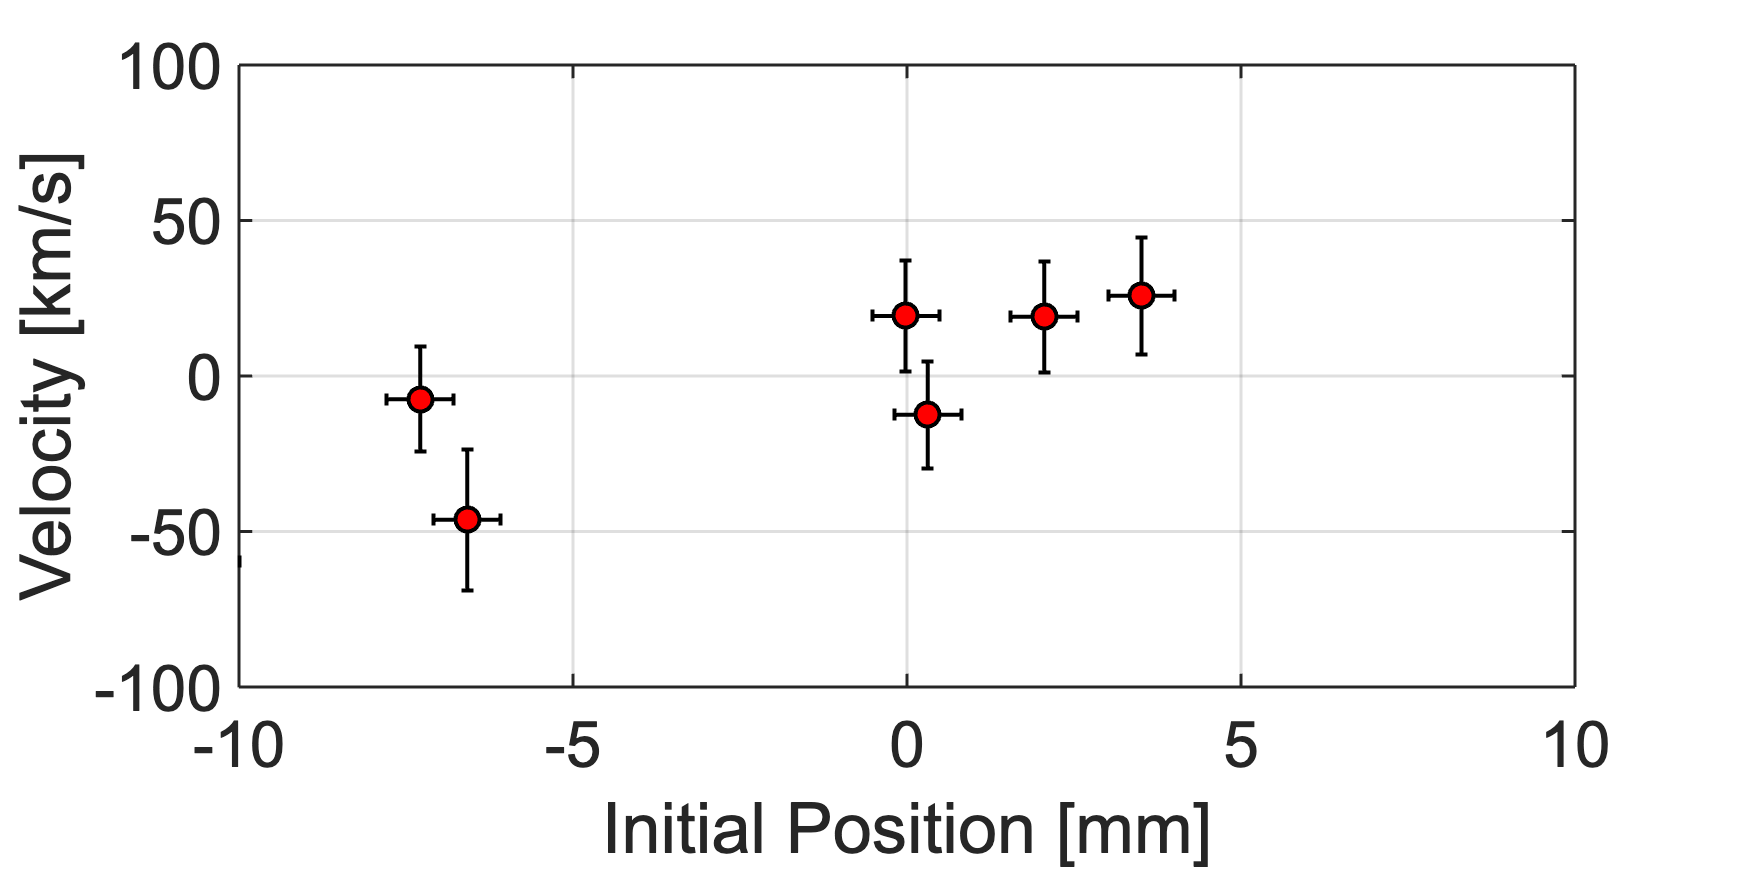





dely = (y1 - y0) * scale; % mm
delt = 30e-9; % s
velocity = dely * 1e-3 / delt; % m / s

ds = 0.5;
dt = 10e-9;
dv = velocity .* sqrt( (ds ./ dely).^2 + ((dt / delt)^2)); 

figure
y0_mm = (y0 - m/2)  * scale; % mm


errorbar(y0_mm,velocity/1e3,dv/1e3,linewidth=2,color='k',linestyle='none'); hold on;
errorbar(y0_mm,velocity/1e3,ds*ones(size(y0_mm)),'horizontal',linewidth=2,color='k',linestyle='none')
plot(y0_mm,velocity/1e3,'o',markersize=12,linewidth=2,color='k',markerfacecolor='r'); hold on;
formatPlots(900,2);
grid(); legend('off');
ylim([-100,100]); xlim([-10,10])
xlabel('Initial Position [mm]'); ylabel('Velocity [km/s]')



display(velocity/1e3);

   25.8268
   19.0888
  -12.4516
   19.3180
  -46.1830
   -7.4737
  -59.5490



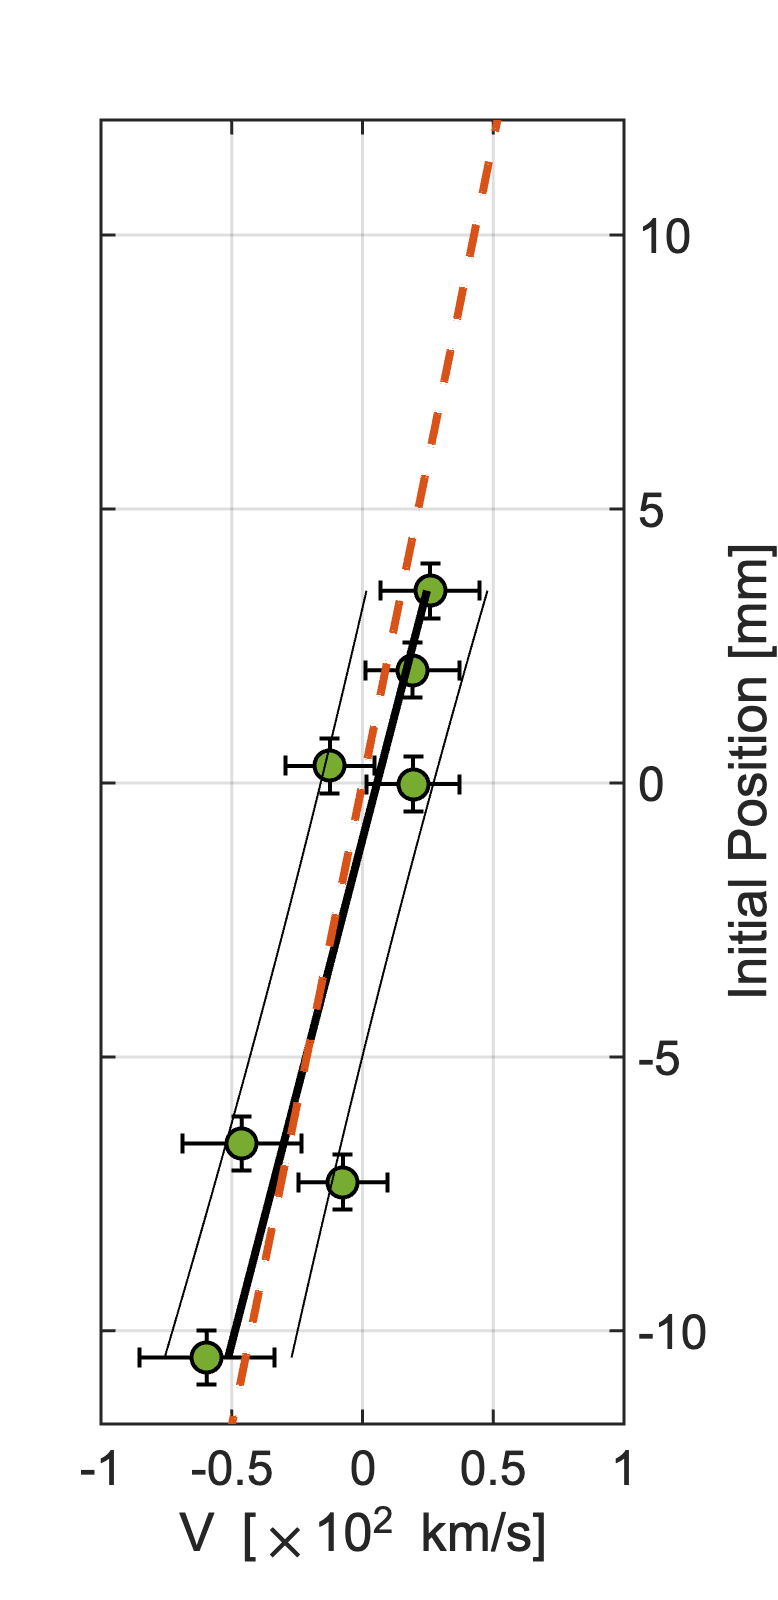

figure
% y0_mm = (y0 - m/2)  * scale; % mm


errorbar(velocity/1e3/1e2,y0_mm,dv/1e3/1e2,'horizontal',linewidth=2,color='k',linestyle='none',capsize=10); hold on;
errorbar(velocity/1e3/1e2,y0_mm,ds*ones(size(y0_mm)),linewidth=2,color='k',linestyle='none',capsize=10)
plot(velocity/1e3/1e2,y0_mm,'o',markersize=15,linewidth=2,color='k',markerfacecolor='#77AC30'); hold on;
formatPlots(900,2);
grid(); legend('off');
xlim([-1,1]); ylim([-11.7,12.1])
ylabel('Initial Position [mm]'); xlabel('V [\times10^2 km/s]')
ytickvals = -10:5:10;
yticks(ytickvals);
xticks([-1,-0.5,0,0.5,1])
set(gca,'YAxisLocation','right');
set(gcf,'Position',[0 0 450 925])
set(gca, 'Fontsize',24);

% Fit 
ft = fit(y0_mm,velocity,'poly1');
xx = linspace(min(y0_mm),max(y0_mm),100);
plot(ft(xx)/1e5,xx,'k-','LineWidth',4,'DisplayName','off');

CIO = predint(ft,xx,0.68,'obs');

% shadedErrorBar(ft(xx)/1e5,xx,(CIO'-ft(xx)')/1e5);

plot(CIO/1e5,xx,'k-','LineWidth',1,'DisplayName','off');


% display(velocity/1e3);


% Simulaion

Yq = dlmread('sims/Yq.txt');
Tid = dlmread('sims/Tid.txt');
V = dlmread('sims/velocity.txt');

v = V(:,1) * 0;

for ii = 220:10:250
t = ii; % ns
idx = find(Tid == t);
v =  v + V(:,idx);
end

Vq = v / numel(220:10:250);


plot(Vq/1e3/1e2,Yq*1e3,'--',linewidth=4,color='#D95319');
set(gca,'TickDir','in')


savePath = checkDir('\Users\rishabhdatta\Dropbox (MIT)\PUFFIN\Writing\Figures\PRL\');

% saveas(gcf,[savePath, 'UXI_velocity.png'])

% SAVE FOR POP
save('UXI1_Velocity.mat','y0_mm','velocity','dv','ds');
savePath = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/Figures_POP/');
saveas(gcf,[savePath 'z3781_UXI1_velocity.png']);

# For POP

# For POP

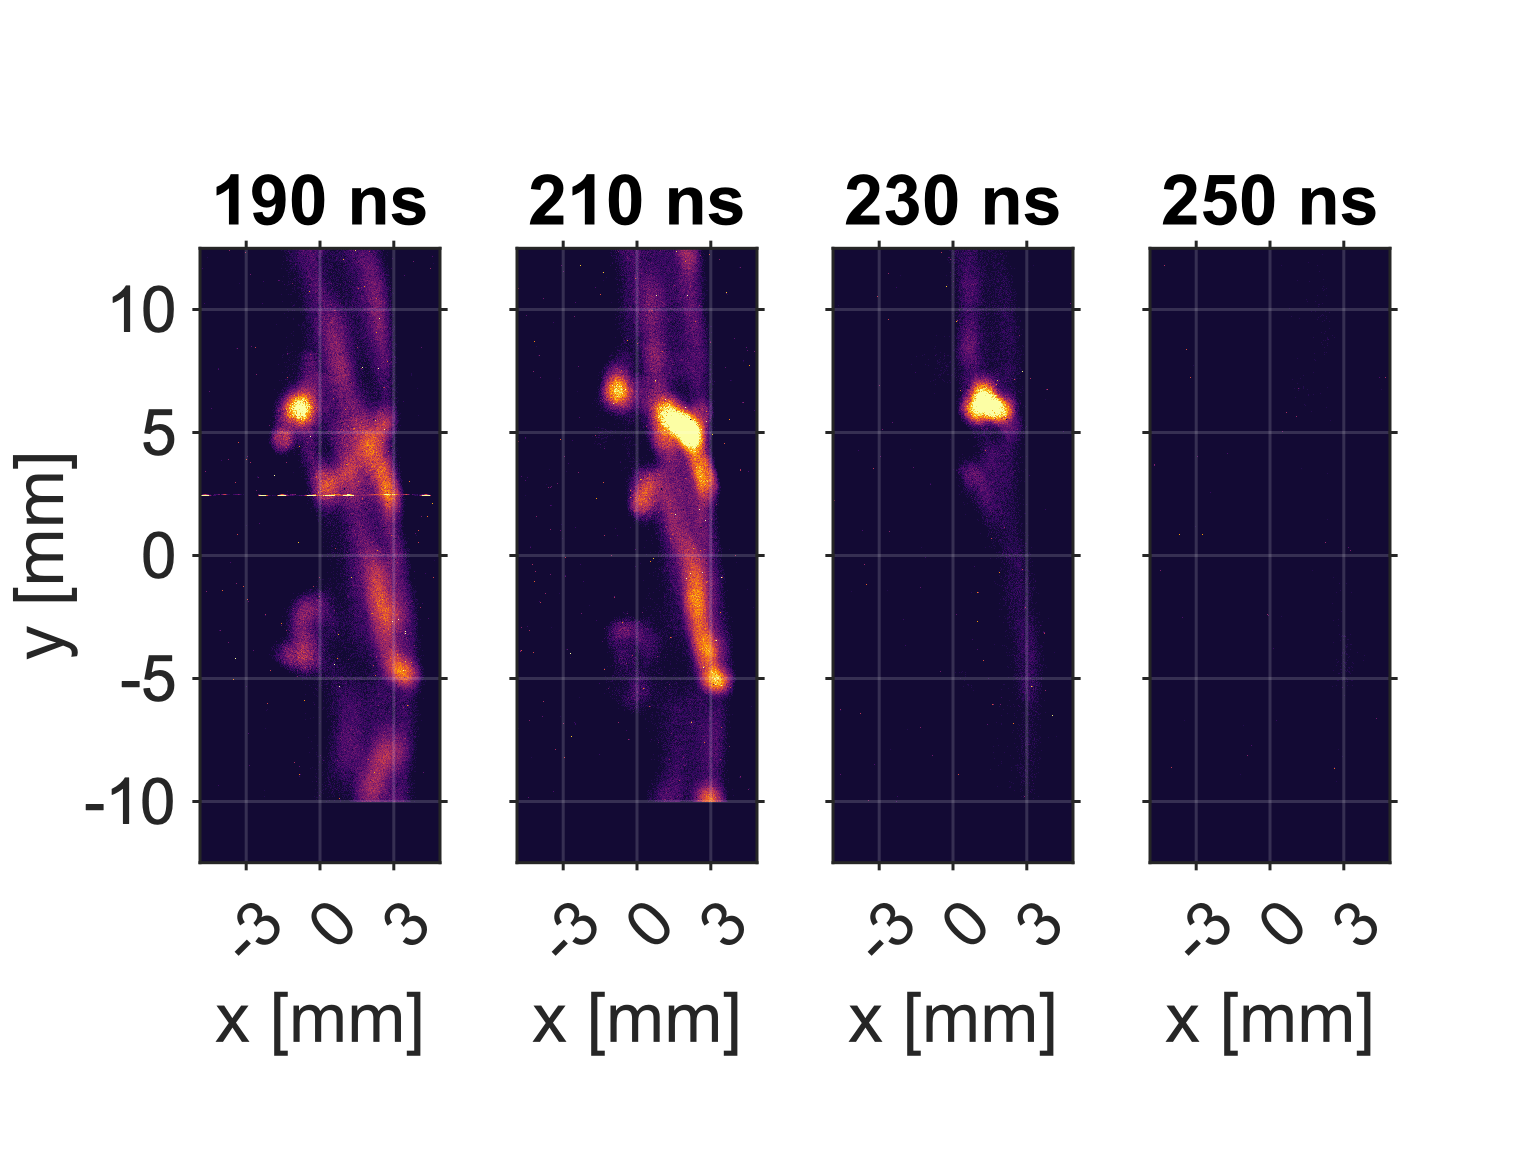

clc; close all; 
camera = 1;
frames = [0,1,2,3];
times = [180,200,220,240] + 10;
f0 = loadUXI(inDir,camera,frames(1));
f1 = loadUXI(inDir,camera,frames(2));
f2 = loadUXI(inDir,camera,frames(3));
f3 = loadUXI(inDir,camera,frames(4));
new = false; % set to true for new
saveDir = checkDir('C:\Users\rdatta\Dropbox (MIT)\PUFFIN\Data\MARZ\UXI\processed');
L = 25;
[m,n] = size(f0);
xtickvals = [-3,0,3];
ytickvals = -10:5:10;
scale = L / m; % mm/px

f0 = flipud(f0);
f1 = flipud(f1);
f2 = flipud(f2);
f3 = flipud(f3);

k = -40; l = 100;
f0 = circshift(f0,[l,k]);
f1 = circshift(f1,[l,k]);
f2 = circshift(f2,[l,k]);
f3 = circshift(f3,[l,k]);

f0(1:l,:) = 0;
f1(1:l,:) = 0;
f2(1:l,:) = 0;
f3(1:l,:) = 0;




figure

subplot(1,4,1)
imagesc(f0);
xlabel('x [mm]'); ylabel('y [mm]');
colormap(inferno());
grid on
ax = gca;
ax.GridColor = [1,1,1];  % [R, G, B]
axis equal
caxis([-2,20])
[m,n] = size(sub_img);
xlim([0,n]); ylim([0,m]);
formatPlots();set(gca, 'Fontsize',24);

set(gca,'YDir','normal')
addScale(scale,f0,xtickvals,ytickvals);
set(gca,'TickDir','out'); 


subplot(1,4,2)
imagesc(f1);
xlabel('x [mm]'); 
% ylabel('y [mm]');
colormap(inferno());
grid on
ax = gca;
ax.GridColor = [1,1,1];  % [R, G, B]
axis equal
caxis([-2,20])
[m,n] = size(sub_img);
formatPlots(); set(gca, 'Fontsize',24);
set(gcf,'Position',[0 0 900 900]);
set(gca,'YDir','normal')
addScale(scale,f1,xtickvals,ytickvals);
set(gca,'TickDir','out'); 
set(gca,'YTickLabel',[])

subplot(1,4,3)
imagesc(f2);
xlabel('x [mm]'); 
% ylabel('y [mm]');
colormap(inferno());
grid on
ax = gca;
ax.GridColor = [1,1,1];  % [R, G, B]
axis equal
caxis([-2,20])
[m,n] = size(sub_img);
title(['C' num2str(camera) ' 220 ns']); 
formatPlots(); set(gca, 'Fontsize',24);
set(gcf,'Position',[0 0 1200 900]);
set(gca,'YDir','normal')
addScale(scale,f2,xtickvals,ytickvals);
set(gca,'TickDir','out'); 
set(gca,'YTickLabel',[])

subplot(1,4,4)
imagesc(f3);
xlabel('x [mm]'); 
% ylabel('y [mm]');
colormap(inferno());
grid on
ax = gca;
ax.GridColor = [1,1,1];  % [R, G, B]
axis equal
caxis([-2,20])
[m,n] = size(sub_img);
title(['C' num2str(camera) ' 240 ns']); 
formatPlots(); set(gca, 'Fontsize',24);
set(gcf,'Position',[0 0 1200 900]);
set(gca,'YDir','normal')
addScale(scale,f2,xtickvals,ytickvals);
set(gca,'TickDir','out'); 
set(gca,'YTickLabel',[])


for ii =1:4
    subplot(1,4,ii)
    xlim([size(f0,2)/2-200,size(f0,2)/2+200]);
    title([num2str(times(ii)) ' ns']); 
    ylim([0,m]);
    set(gca, 'Fontsize',32);
end

savePath = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/Figures_POP/');
saveas(gcf,[savePath 'z3781_UXI1.png']);